**Solving for unknown in rolling mode**

**condition**

Trajectory will consists of $x\;,y$    (2)

Unknown LHS: $\psi ,\theta ,\varphi ,\beta_S ,\alpha_p \;\textrm{and}\;\textrm{its}\;\textrm{derevative}$.    (5)

Unknown RHS: $\lambda_x ,\lambda_y ,\tau_{\beta s} ,\tau_{\alpha p}$     (4)

Summary: overall 9 unknown and we have 7+2 equation.(L7+C2)

**Test: Rolling path -> Circle path**

**Test: Trajectory generation**

constrain equation

x(path) = x(generalize coordinate) 

y(path) = y(generalize coordinate)

syms omega R t
omega = 20      % [rad/s]

omega = 20

R = 20          % [m]

R = 20

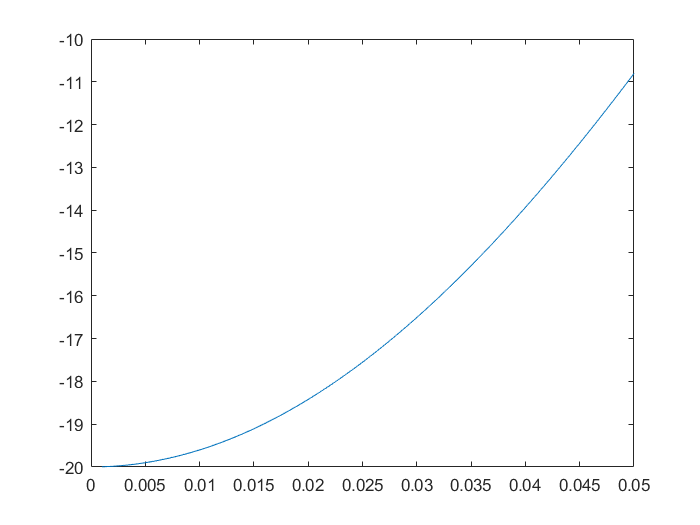

%Rotation at same velocity
S_x = -R*cos(omega*t);
S_y = R*sin(omega*t);

V_x = omega*R*sin(omega*t);
V_y = omega*R*cos(omega*t);

a_x = (omega^2)*R*cos(omega*t);
a_y = -(omega^2)*R*sin(omega*t);

S_data = sym('s',[20 3]);%[S_x S_y beta_s t]
V_data = sym('v',[20 3]);%[V_x V_y beta_s_dot t]
a_data = sym('a',[20 3]);%[a_x a_y beta_s_ddot t]



for i = 1:50
    S_data(i,1) = subs(S_x,t,0.001*i);
    S_data(i,2) = subs(S_y,t,0.001*i);
    S_data(i,3) = 0;
    S_data(i,4) = 0.001*i;
    
    V_data(i,1) = subs(V_x,t,0.001*i);
    V_data(i,2) = subs(V_y,t,0.001*i);
    V_data(i,3) = 0;
    V_data(i,4) = 0.001*i;
    
    a_data(i,1) = subs(a_x,t,0.001*i);
    a_data(i,2) = subs(a_y,t,0.001*i);
    a_data(i,3) = 0;
    a_data(i,4) = 0.001*i;
end
S_data = eval(S_data);
V_data = eval(V_data);
a_data = eval(a_data);

S_data;%[S_x S_y beta_s t]
V_data;%[V_x V_y beta_s_dot t]
a_data;%[a_x a_y beta_s_ddot t]
plot(S_data(:,4),S_data(:,1))

**Converting variable in derivative form to normal form.**

qq_dot_t = qt ;

eq = [L-Q];


qt = [0 0 psi1(t) 0 0 0 alpha1_p(t)].';
qt_dot = diff(qt);
qt_ddot = diff(qt_dot);
%we need to change theses parameter back to ..
syms x y psi theta phi beta_s alpha_p
qj = [x y psi theta phi beta_s alpha_p].' ;
syms x_dot y_dot psi_dot theta_dot phi_dot beta_s_dot alpha_p_dot
qj_dot = [x_dot y_dot psi_dot theta_dot phi_dot beta_s_dot alpha_p_dot].' ;
syms x_ddot y_ddot psi_ddot theta_ddot phi_ddot beta_s_ddot alpha_p_ddot
qj_ddot = [x_ddot y_ddot psi_ddot theta_ddot phi_ddot beta_s_ddot alpha_p_ddot].' ;
x = 0;
y = 0;
theta = 0;
phi = 0;
beta_s = 0;

x_dot = 0;
y_dot = 0;
theta_dot = 0;
phi_dot = 0;
beta_s_dot = 0;

x_ddot = 0;
y_ddot = 0;
theta_ddot = 0;
phi_ddot = 0;
beta_s_ddot = 0;

%subs
for i = 1:7
   eq = subs(eq,qt_ddot(i),qj_ddot(i));
   eq = subs(eq,qt_dot(i),qj_dot(i));
   eq = subs(eq,qt(i),qj(i));
end


**try to subsitutube values as much as possible before solving the equation**

- **Constant variables (one time only)**

- **Constant variables due to condition (one time only)**

- **Trajectory variables ( depends on time )**

- **Time derivative variable ( depends on time )**

**1.Constant variables (one time only)**

m_bd Ixx_bd Iyy_bd Izz_bd g_w

m_c  Ixx_c Iyy_c Izz_c 

m_s  Ixx_s Iyy_s Izz_s 

Z_plate Z_stator Z_Pt Z_Pd

%g_w = -9.81;
Mcvs = [m_bd Ixx_bd Iyy_bd Izz_bd m_s Ixx_s Iyy_s Izz_s m_p Ixx_p Iyy_p Izz_p g_w];
Dcvs = [Z_bd Z_p];
Mcv = [10 10 10 10 10 10 10 10 10 10 10 10 -9.81];
Dcv = [5 5];

r = 0.4; %radius of drone
[r,c] = size(Mcvs);
for i = 1:c;
    eq = subs(eq,Mcvs(i),Mcv(i));
end

[r,c] = size(Dcvs);
for i = 1:c;
    eq = subs(eq,Dcvs(i),Dcv(i));
end
eq = eval(eq);

**Dealing with RHS and LHS equations.**

eq = $\left\lbrack \begin{array}{c}
\textrm{L8}-Q\\
A\left(q\right)\ddot{q} +\;\dot{A} \left(q\right)\dot{q} 
\end{array}\right\rbrack =0$

eqf = matlabFunction(eq)

eqf = function_handle with value:
    @(Ixx_p,Ixx_s,alpha_p,alpha_p_dot,alpha_p_ddot,m_p,psi,psi_dot,psi_ddot,tau_beta_s,tau_alpha_p)[cos(psi).*(-9.81e2./2.0)+psi_dot.*psi_ddot.*2.6e2-m_p.*(alpha_p_dot+psi_dot).^2.*(2.5e1./2.0)-m_p.*cos(alpha_p+psi).*(9.81e2./2.0e1)-Ixx_s.*psi_dot.^2.*(1.0./2.0)-psi_dot.^2.*1.3e2+m_p.*(alpha_p_dot+psi_dot).*(alpha_p_ddot+psi_ddot).*2.5e1+Ixx_s.*psi_dot.*psi_ddot-Ixx_p.*(alpha_p_dot+psi_dot).*(alpha_p_dot.*(1.0./2.0)+psi_dot.*(1.0./2.0))+Ixx_p.*(alpha_p_dot+psi_dot).*(alpha_p_ddot.*(1.0./2.0)+psi_ddot.*(1.0./2.0))+Ixx_p.*(alpha_p_ddot+psi_ddot).*(alpha_p_dot.*(1.0./2.0)+psi_dot.*(1.0./2.0));cos(psi).*(-9.81e2./2.0)+psi_dot.*psi_ddot.*2.6e2-m_p.*(alpha_p_dot+psi_dot).^2.*(2.5e1./2.0)-m_p.*cos(alpha_p+psi).*(9.81e2./2.0e1)-Ixx_s.*psi_dot.^2.*(1.0./2.0)-psi_dot.^2.*1.3e2+m_p.*(alpha_p_dot+psi_dot).*(alpha_p_ddot+psi_ddot).*2.5e1+Ixx_s.*psi_dot.*psi_ddot-Ixx_p.*(alpha_p_dot+psi_dot).*(alpha_p_dot.*(1.0./2.0)+psi_dot.*(1.0./2.0))+Ixx_p.*(alpha_p_dot+psi_dot)

root0 = [0;0;0;0;0;0;0;0];
% root = fsolve(eq,root0)

**2.Constant variables due to condition (one time only)**

%RHS = subs(RHS,beta_c,0);
%RHS = subs(RHS,beta_c(t)_dot,0);
%RHS = subs(RHS,beta_c(t)_dotdot,0);

**3.Trajectory variables ( depends on time )**

 x y z and phi is taken from trajectory (also time derivative of its)

**4.Time derivative variable ( depends on time )**

psi theta beta_s alpha_s        

**so the time derivative unknown are** psi theta beta_s alpha_s

Boundary condition:  $\left\lbrack \begin{array}{c}
\psi  & \theta  & \beta_s  & \alpha_s 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0
\end{array}\right\rbrack$

$\left\lbrack \begin{array}{c}
\psi^{\ldotp }  & \theta^{\ldotp }  & \overset{\ldotp }{\beta_s }  & \overset{\ldotp }{\alpha_s } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0
\end{array}\right\rbrack$ ;

$\left\lbrack \begin{array}{c}
\psi^{\ldotp \ldotp }  & \theta^{\ldotp \ldotp }  & \overset{\ldotp \ldotp }{\beta_s }  & \overset{\ldotp \ldotp }{\alpha_s } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0 & 0 & 0 & 0
\end{array}\right\rbrack$ ;